# Set Page Margins in a PDF Report

This example shows how to define page margins in a PDF report. You can define top, bottom, left, right margins for a PDF page, plus its header, footer and gutter sizes.

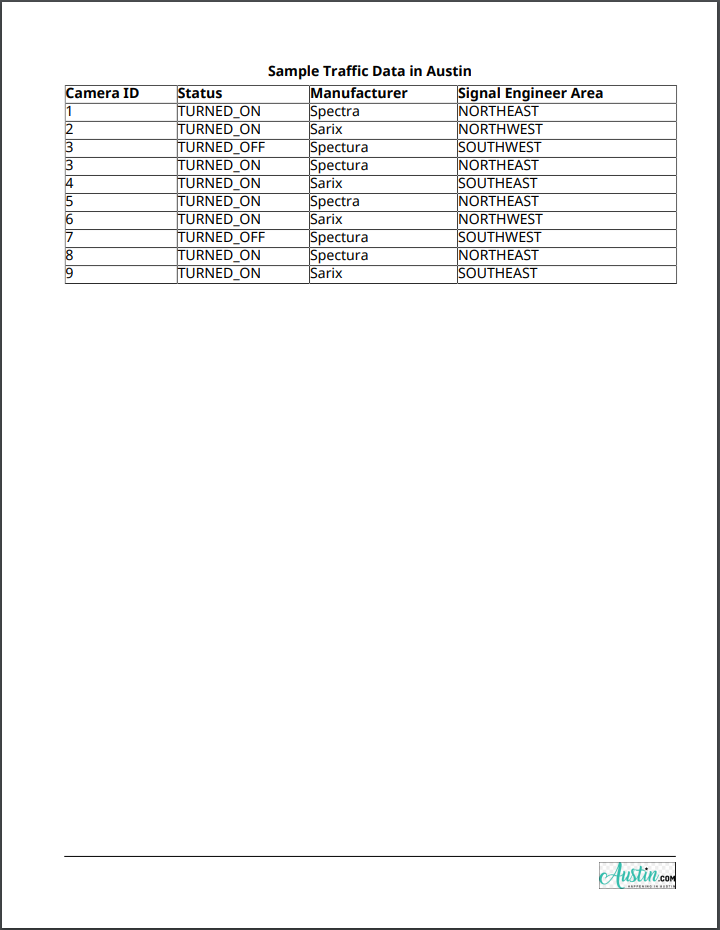

## Create Report

Import the DOM API packages so you do not have to use long, fully-qualified class names

import mlreportgen.dom.*;

Create and open a report.

d = Document('myreport', 'pdf');
open(d);

## Create PDF Page Header

Get the current page layout object.

currentLayout = d.CurrentPageLayout;

Create a page header definition for the PDF document.

pdfheader = PDFPageHeader();

Create a DOM `Paragraph` object and make it center aligned and bold. Set its font size to 12pt. Append it to the `PDFPageHeader` object.

p = Paragraph('Sample Traffic Data in Austin');
p.Style = [p.Style, {HAlign('center'), Bold(true), FontSize('12pt')}];
append(pdfheader, p);

Assign the created `pdfheader` object to the `PageHeaders` of the current page layout.

currentLayout.PageHeaders = pdfheader;

## Create Body Content

Create cell arrays for the styles to be used by the formal table and its table entries.

dataTableStyle = {Border('solid'), ColSep('solid'), RowSep('solid'), Width('100%')...
    OuterMargin('0pt', '0pt', '0pt', '0pt')};

Create some sample data from the Austin traffic camera to include in the table. Then create a `FormalTable` object and include the sample data in the Header and Body sections.

dataHeader = {'Camera ID', 'Status', 'Manufacturer', 'Signal Engineer Area'};
dataBody = {'1', 'TURNED_ON', 'Spectra', 'NORTHEAST';
    '2', 'TURNED_ON', 'Sarix', 'NORTHWEST';
    '3', 'TURNED_OFF', 'Spectura', 'SOUTHWEST';
    '3', 'TURNED_ON', 'Spectura', 'NORTHEAST';
    '4', 'TURNED_ON', 'Sarix', 'SOUTHEAST';
    '5', 'TURNED_ON', 'Spectra', 'NORTHEAST';
    '6', 'TURNED_ON', 'Sarix', 'NORTHWEST';
    '7', 'TURNED_OFF', 'Spectura', 'SOUTHWEST';
    '8', 'TURNED_ON', 'Spectura', 'NORTHEAST';
    '9', 'TURNED_ON', 'Sarix', 'SOUTHEAST'};
dataTable = FormalTable(dataHeader, dataBody);
dataTable.Header.Style = [dataTable.Header.Style {Bold}];
dataTable.Style = [dataTable.Style dataTableStyle];
append(d, dataTable);

## Set Top Margin and Header Size

PDF page headers and footers are fixed in size. The total height from top of the page to the body content is the value of the `Top` property of the `PageMargins` object plus the value of the `Header` property. 

Set the `Top` margin property to 0.75 inches. To accommodate the 12 pts `Paragraph` created in the PDF Header, set the header size to 0.25 inches. 1 inch equals 72 pts, so 0.25 inches equal 18 pts. The `Paragraph` content occupies only 12 pts, so 0.25 inches is enough to accommodate the header. The body content starts 1 inch from the top of the page with the header height of 0.25 inches.

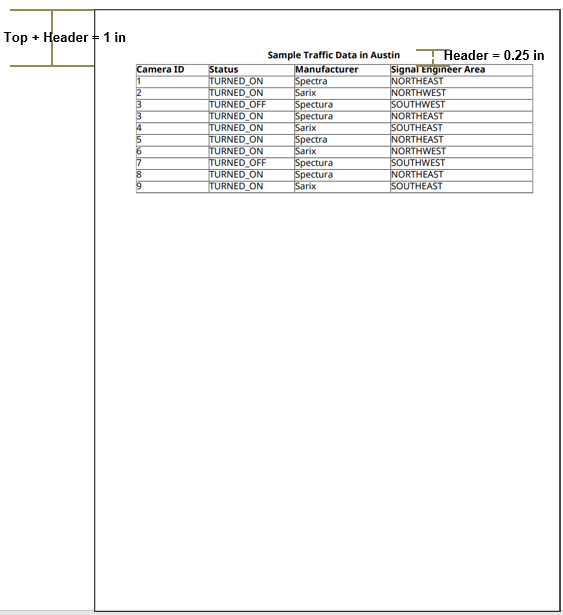

currentLayout.PageMargins.Top = '0.75in';
currentLayout.PageMargins.Header = '0.25in';

## Create PDF Page Footer

Create a page footer definition for the PDF document. 

pdffooter = PDFPageFooter();

Append a horizontal rule to the `pdffooter` object.

append(pdffooter, HorizontalRule());

Append an image to the `pdffooter` object. Use the DOM `ScaleToFit` format to scale the image to fit in the page. Assign the created `pdffooter` object to the `PageFooters` of the current page layout.

imgStyle = {ScaleToFit(true), HAlign('right'), Height('0.30in')};
img = Image('Logo.Png');
img.Style = imgStyle;
append(pdffooter, img);
currentLayout.PageFooters = pdffooter;

## Set Bottom Margin and Footer Size

The distance from the bottom of the page to the body content is the value of `Bottom` property of the PageMargins object plus the value of the `Footer` property.

Set the `Bottom` property value to 0.5 inches. To accommodate the 0.30 in height `Image `and the horizontal rule in the footer, set the `Footer` property value to 0.5 inches. This makes the distance from the bottom of the page to the body content 1 inch.

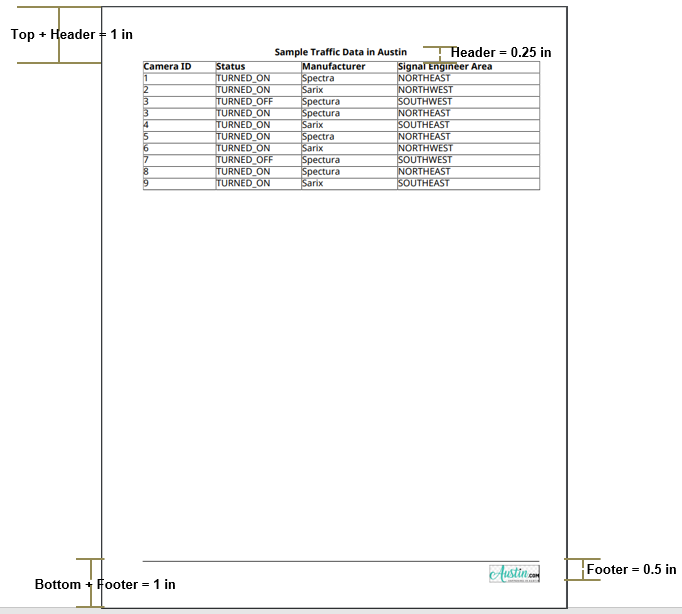

currentLayout.PageMargins.Bottom = '0.5in';
currentLayout.PageMargins.Footer = '0.5in';

## Set Left Margin, Right Margin and Gutter Size

This example uses the `Gutter` setting to leave room on the left side of the page for binding the report. `The Gutter` size is set to 0.25 inches and `Left` margin is set to 0.5 inches. So, the content starts from 0.75 inches(left margin + gutter) from the left side of the page. The `Right` margin is set to 0.5 inches.

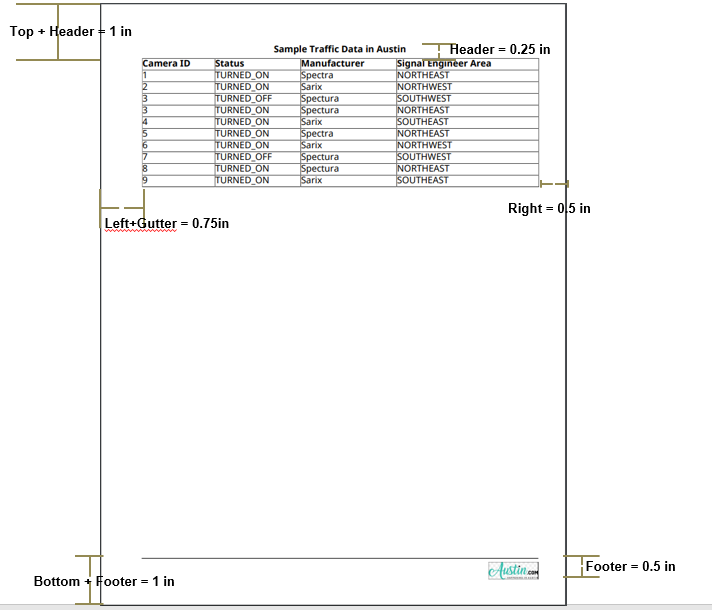

currentLayout.PageMargins.Gutter = '0.25in';
currentLayout.PageMargins.Left = '0.5in';
currentLayout.PageMargins.Right = '0.5in';

Generate and display the report.

close(d);
rptview(d.OutputPath);

*Copyright 2019 The MathWorks, Inc.*